## Parametrización de la Ruta

clear all
%Se define el parámetro l como el 40% del alcance horizontal
horizontal_reach=1.225;
l=0.4*horizontal_reach

l = 0.4900

l=0.48;
%Se parametriza la figura
r=0.3*l;
n=15;

tramo1=[linspace(0,l-r,n)' zeros(n,2)];

theta=linspace(-pi/2,pi/2,n);
cx=(l-r);cy=r;cz=0;
tramo2=[cx+r*cos(theta)' cy+r*sin(theta)' cz+0.*theta'];

tramo3=[tramo2(end,:);linspace(l-r,0,n)' 2*r.*ones(n,1) zeros(n,1)];

tramo4=[tramo3(end,:);zeros(n,1) linspace(2*r,0,n)' zeros(n,1)];

path=[tramo1;tramo2;tramo3;tramo4];

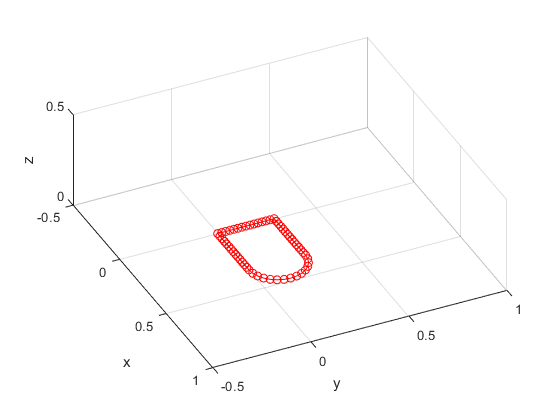

%Comprobamos que la figura esté bien parametrizada en el plano xy
plot3(path(:,1),path(:,2),path(:,3),'-ro')
grid on
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
xlim([-0.500 1.000])
ylim([-0.500 1.000])
zlim([0.000 0.500])
view([64.545 33.537])

clf
%Establecemos ahora la transformación:
R0_t=rotx(45,'deg')

R0_t =     1.0000         0         0
         0    0.7071   -0.7071
         0    0.7071    0.7071


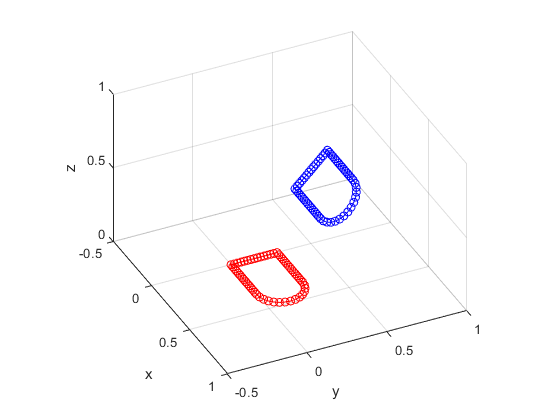

P0_t=[0 0.4 0.4];
%Multiplicamos para hallar la figura en el plano de trabajo
path_=0.*path;
for i=1:length(path(:,1))
    path_(i,:)=R0_t*path(i,:)'+P0_t';
end
plot3(path(:,1),path(:,2),path(:,3),'-ro')
hold on
plot3(path_(:,1),path_(:,2),path_(:,3),'-bo')
grid on
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
xlim([-0.500 1.000])
ylim([-0.500 1.000])
zlim([0.000  1.00])
view([64.545 33.537])
hold off